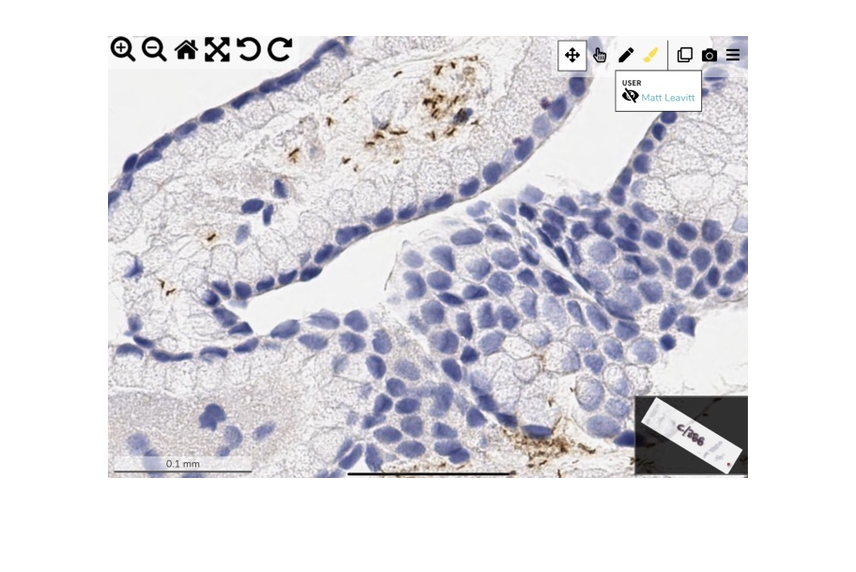

addpath('/Users/karthikdharmarajan/Downloads/H.pylori/branches/Karthik')

MasterImage = imread('MasterImage','jpeg');
AnnotatedMasterImage = imread('AnnotatedMasterImage.jpeg');

imshow(MasterImage)

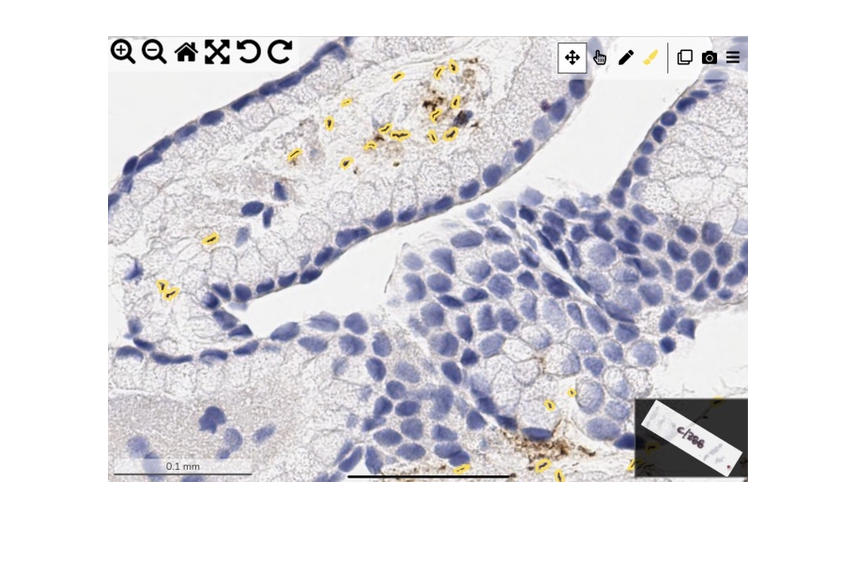

imshow(AnnotatedMasterImage)

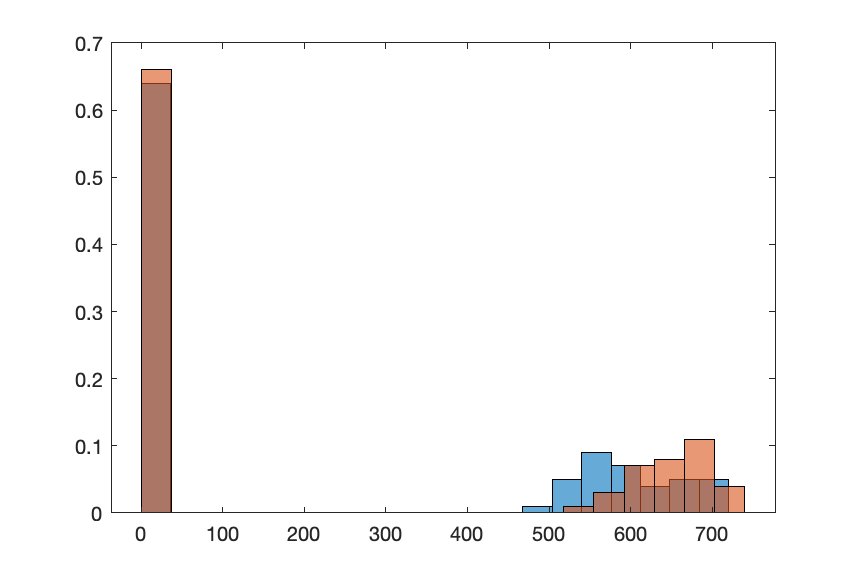


ExamplePositive = imread('ExamplePositive.jpeg');
ExampleNegative = imread('ExampleNegative.jpeg');

[rEP,cEP] = size(ExamplePositive);
[rEN,cEN] = size(ExampleNegative);

totalRGBValue = [];

for i = 1:rEP
    for j = 1:cEP
        temp = sum(impixel(ExamplePositive,i,j));
        if(temp > 500)
            totalRGBValue(i * j) = temp;
        end
    end
end


totalRGBValue2 = [];

for i = 1:rEN
    for j = 1:cEN
        temp = sum(impixel(ExampleNegative,i,j));
        if(temp > 500)
            totalRGBValue2(i * j) = temp;
        end
    end
end

distributionRGB = histogram(totalRGBValue,20,'Normalization','probability');

hold on

distributionRGB2 = histogram(totalRGBValue2,20,'Normalization','probability');


hold off

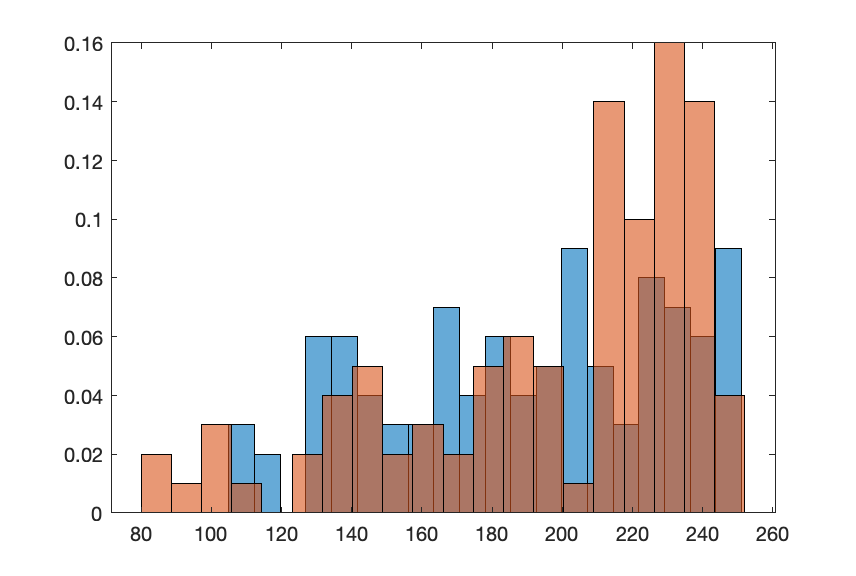


distributionR = histogram(ExamplePositive(:,:,1),20,'Normalization','probability');

hold on

distributionR2 = histogram(ExampleNegative(:,:,1),20,'Normalization','probability');

hold off

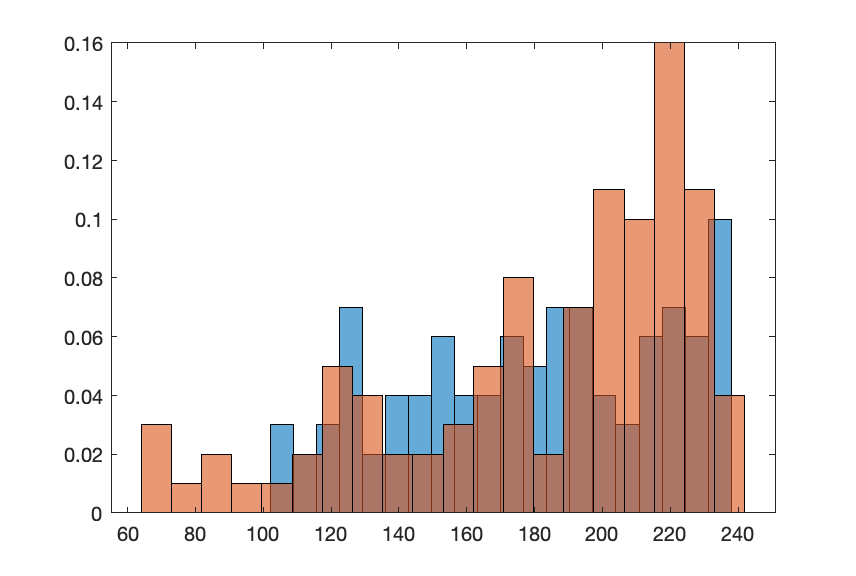


distributionG = histogram(ExamplePositive(:,:,2),20,'Normalization','probability');

hold on

distributionG2 = histogram(ExampleNegative(:,:,2),20,'Normalization','probability');

hold off

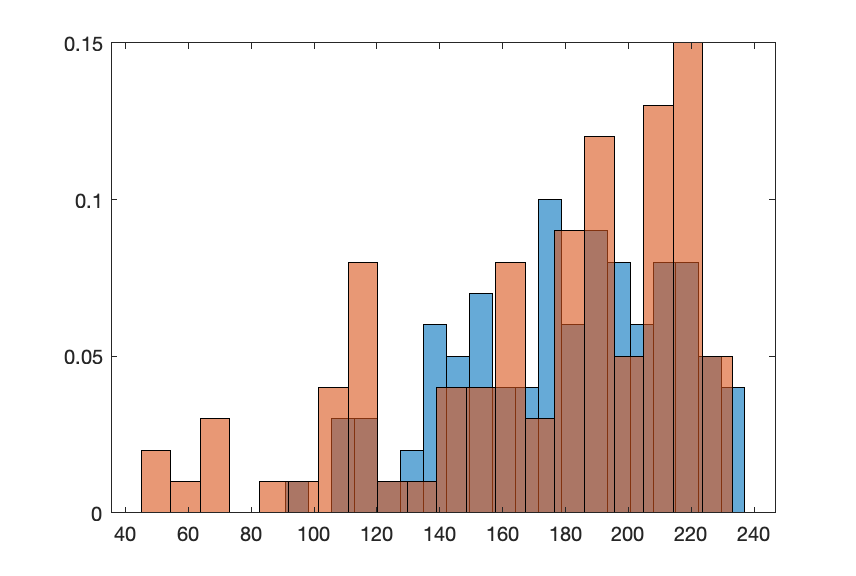


distributionB = histogram(ExamplePositive(:,:,3),20,'Normalization','probability');

hold on

distributionB2 = histogram(ExampleNegative(:,:,3),20,'Normalization','probability');